%calculating the mean first passage time analytically/numerically 
%to investigate the optima position of 1 mismatch from the
%perspective of RNA/DNA toehold exchange including spontaneous incumbent
%dissociation

b = 20 %define branch migration domain length

b =     20


g = 4 %define invader toehold length

g =      4


g2 = 1 %define incumbent toehold length

g2 =      1



bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 =     21



R = 1.987/1000 %universal gas constant in kcal/K/mol 

R =    0.001987000000000


temp = 298.15%temperature in K

temp =      2.981500000000000e+02


%free energy parameters
dGassoc = 2.6*R*temp

dGassoc =    1.540302530000000


dGbp = -2.52*R*temp

dGbp =   -1.492908606000000


dGrd = -0.3*R*temp

dGrd =   -0.177727215000000


dGp = 3.6*R*temp

dGp =    2.132726580000000


dGmm = 9.5*R*temp

dGmm =    5.628028475000000


dGbm = 7.4*R*temp

dGbm =    4.383937970000000


%absolute rate constant
k_bp = 5.4*10^7

k_bp =     54000000


k_eff = zeros(1,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through the mismatch positions 
for m = 1:20
    m

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Crm = k_bp* exp((dGmm - dGbm + dGrd)/(R*temp)) %I have added + dGrd
    k_Crm_end = k_bp * exp((dGmm - dGbm - dGp + dGrd)/(R*temp)) %I have added + dGrd
    k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp*exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
       
    if m == b 
        %create arrays of forward and reverse transition rates for
        %mismatch system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(g2 + b - m + 1) = k_Crm_end
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2+ 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
    else
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(g2 + b - m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2+ 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff(Pn) * Pn_jN_1_perf(Pn);
    end
    
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8));%effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1)%probability of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8));%effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf)%prob of being in unbound state for mismatch-free system
end

m =      1


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf = 	1.0e+06 *

                   0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb = 	1.0e+06 *

                   0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb = 	1.0e+08 *

                   0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff = 	1.0e+05 *

                   0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

   1.431690380515020                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      2


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf = 	1.0e+06 *

                   0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb = 	1.0e+06 *

                   0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb = 	1.0e+08 *

                   0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff = 	1.0e+05 *

                   0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

   1.431690380515020   1.058613239921743                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      3


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf = 	1.0e+06 *

                   0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb = 	1.0e+06 *

                   0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb = 	1.0e+08 *

                   0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff = 	1.0e+05 *

                   0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

   1.431690380515020   1.058613239921743   0.782230843637524                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      4


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf = 	1.0e+06 *

                   0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      5


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      6


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      7


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      8


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      9


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =     10


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =     11


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =     12


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0                   0


m =     13


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0                   0


m =     14


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734   0.019720786349704                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898   0.998204225206059                   0                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0                   0


m =     15


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734   0.019720786349704   0.007316709415586                   0                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898   0.998204225206059   0.997710376373312                   0                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0                   0


m =     16


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734   0.019720786349704   0.007316709415586   0.000997891488334                   0                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898   0.998204225206059   0.997710376373312   0.997481904506616                   0                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0                   0


m =     17


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734   0.019720786349704   0.007316709415586   0.000997891488334   0.000249632224864                   0                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898   0.998204225206059   0.997710376373312   0.997481904506616   0.998916375915283                   0                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0                   0


m =     18


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   0.000244526678759   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734   0.019720786349704   0.007316709415586   0.000997891488334   0.000249632224864   0.000200729348738                   0                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898   0.998204225206059   0.997710376373312   0.997481904506616   0.998916375915283   0.999614937342106                   0                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0                   0


m =     19


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   0.000006681379101   3.266809630782991   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.000244526678759   0.032187209062827   0.032187209062827   0.032187209062827   0.032187209062827                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734   0.019720786349704   0.007316709415586   0.000997891488334   0.000249632224864   0.000200729348738   0.000197982976217                   0


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898   0.998204225206059   0.997710376373312   0.997481904506616   0.998916375915283   0.999614937342106   0.999682241680936                   0


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375                   0


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001                   0


m =     20


k_AB1 =    0.200538661178701


k_B1A =      3.218720906282724e+06


k_BC1ji =      3.218720906282724e+06


k_C1f =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cr =      2.445266787588704e+04


k_Crm =      3.266809630782991e+08


k_Crm_end =      8.926139963965673e+06


k_DC =      6.681379101365640e+02


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000668137910137   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Kb =                    0   8.926139963965673   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   0.024452667875887   3.218720906282724   3.218720906282724   3.218720906282724   3.218720906282724                   0


Koff =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    1.431690380515020   1.058613239921743   0.782230843637524   0.577481657304037   0.425799633161575   0.313430695977225   0.230185564065449   0.168515812723979   0.122829380907086   0.088983285302795   0.063906118598089   0.045304462879754   0.031337865978734   0.019720786349704   0.007316709415586   0.000997891488334   0.000249632224864   0.000200729348738   0.000197982976217   0.000197900209720


prob_unbound =    0.999687251439475   0.999676409151190   0.999661775648401   0.999642026255481   0.999615374292769   0.999579410683297   0.999530888550437   0.999465434603911   0.999377163823476   0.999258168101064   0.999097844810683   0.998882034772992   0.998592002434898   0.998204225206059   0.997710376373312   0.997481904506616   0.998916375915283   0.999614937342106   0.999682241680936   0.999685073938511


first_pass_time_perf =   19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375  19.790005863444375


prob_unbound_perf =    0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001   0.999685082620001



%avr_k_eff = sqrt(k_eff .* flip(DNA_RNA_k_eff)) %average effective rate
%constant for RNA/DNA and DNA/RNA directions for mismatch system
%avr_k_eff_perf = sqrt(k_eff_perf .* flip(DNA_RNA_k_eff_perf)) %average
%effective rate constant for RNA/DNA and DNA/RNA directions for
%mismatch-free system
%[val, idx] = max(avr_k_eff(:)) %determine maximum average effective rate
%constant
%log10(val)
%log10(avr_k_eff(1))

[val, idx] = max(k_eff(:)) %determine maximum RNA/DNA effective rate constant

val =      1.010610348939667e+06


idx =     20


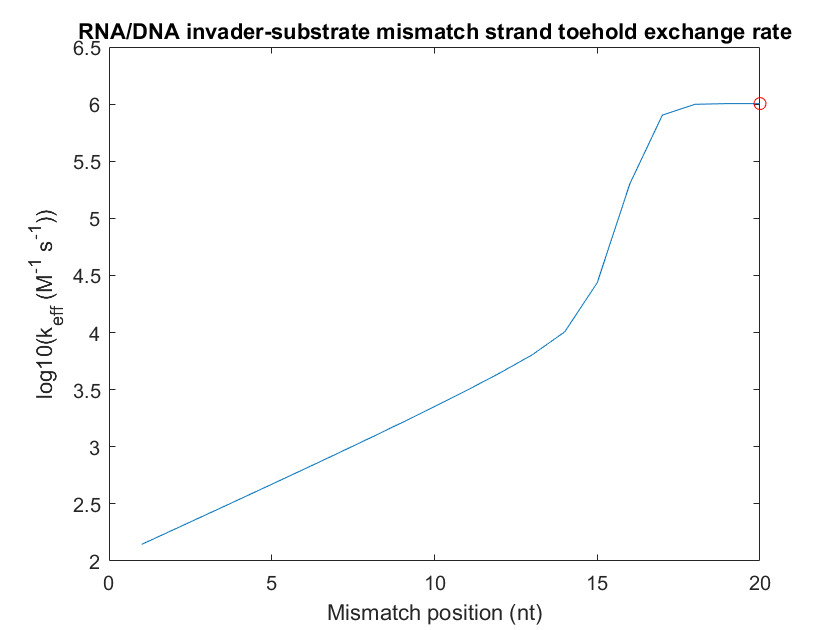


plot(1:20, log10(k_eff))
xlabel('Mismatch position (nt)')
ylabel('log10(k_e_f_f (M^-^1 s^-^1))')
title('RNA/DNA invader-substrate mismatch strand toehold exchange rate')
hold on 
plot(idx, log10(val), 'ro')
hold off 


%plot(1:20, log10(avr_k_eff))
%xlabel('Mismatch position (nt)')
%ylabel('log10(k_e_f_f (M^-^1 s^-^1))')
%title('RNA/DNA invader-substrate mismatch strand toehold exchange rate')
%hold on 
%plot(idx, log10(val), 'ro')
%plot(1:20, log10(avr_k_eff_perf), 'k--')
%hold off 